# Test CNN2D optimization, training and Testing

## Load the Szenario or build from scratch

clearvars;
%LoadToolbox
addPaths;

%DataLocation
locationData = 'Data\';

loadStruct = [];
%Struct DataLocation
loadStruct.fileNameDataAll = [convertCharsToStrings([locationData 'sensorA.mat'])];
loadStruct.fileNameTargetAll = [convertCharsToStrings([locationData 'target.mat'])];
loadStruct.targetGas = 'acetone';

% If multiple Sensors should be used
%loadStruct.fileNameDataAll = [convertCharsToStrings([locationData 'sensorA.mat']);convertCharsToStrings([locationData 'sensorB.mat'])];
%loadStruct.fileNameTargetAll = [convertCharsToStrings([locationData 'target.mat']);convertCharsToStrings([locationData 'target.mat'])];

%Used Method %see LoadDataFull 1: 70% 10% 20% Split
loadStruct.loadMethod = 1;

%Expected Input Dimensions
loadStruct.dataSize = [4,1440];

%Expected Output Dimensions
loadStruct.Outputsize = 1;

%Specify Regression or Classification
loadStruct.Regression = true;


%SaveFlag = 
loadStruct.saveFlag = true;

%Random Flag; False: Reproduzable random Samples; True: in every execution Random
loadStruct.randomFlag = false;

%NormalizeInput 
loadStruct.normFlag = true;

loadStruct.OcclusionFlag = false;

loadStruct.saveName = [locationData 'Szenario_SA_1_Acetone.mat'];

%Not the exact split is performed than in the original data (~20 UGMs less in test Set)
[data,target] = loadDataFull(loadStruct);

Data\sensorA.mat
acetone
Split
RandomFlag
   0



## If alredy Optimized -> Train and Test TCOCNN

%Generate Model without optim hyperparameter
paraStore = [locationData 'acetoneParams.mat'];
load(paraStore);
tcocnnTest2 = TCOCNN(loadStruct.dataSize,loadStruct.Outputsize,loadStruct.Regression,optim);


%With already optimized variables start training directly
tcocnnTest2.train(data.train,target.train);
%Predict Test Data
pred = tcocnnTest2.apply(data.test);
disp(helpers.RMSE.loss(pred,target.test));

   16.4623



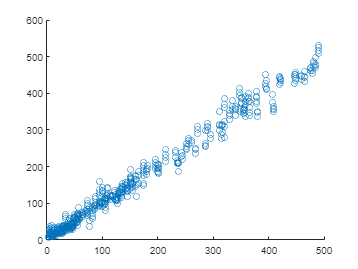


%display target vs pred
figure()
scatter(target.test,pred)

xaiOcc = tcocnnTest2.customOcclusion(data.train,data.test,'custom');

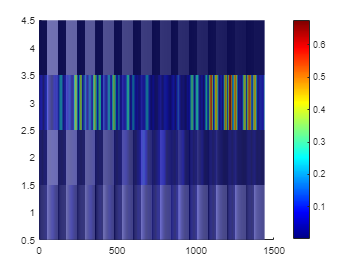

helpers.ImageDisp(mean(abs(xaiOcc(:,:,:,:)),4),data.train(:,:,1,1));

meanResponse = mean(data.train(:,:,1,:),4);
xaiOccMeanId = mean(abs(xaiOcc(:,:,:,:)),4)<0.10;

dataRed = data;
for i = 1:size(dataRed.train,4)
    temp = squeeze(dataRed.train(:,:,1,i));
    temp(xaiOccMeanId) = meanResponse(xaiOccMeanId);
    dataRed.train(:,:,1,i) = temp;
end

for i = 1:size(dataRed.val,4)
    temp = squeeze(dataRed.val(:,:,1,i));
    temp(xaiOccMeanId) = meanResponse(xaiOccMeanId);
    dataRed.val(:,:,1,i) = temp;
end

for i = 1:size(dataRed.test,4)
    temp = squeeze(dataRed.test(:,:,1,i));
    temp(xaiOccMeanId) = meanResponse(xaiOccMeanId);
    dataRed.test(:,:,1,i) = temp;
end

%Generate Model without optim hyperparameter
paraStore = [locationData 'acetoneParams.mat'];
load(paraStore);
tcocnnTest2 = TCOCNN(loadStruct.dataSize,loadStruct.Outputsize,loadStruct.Regression,optim);


%With already optimized variables start training directly
tcocnnTest2.train(dataRed.train,target.train);
%Predict Test Data
pred = tcocnnTest2.apply(dataRed.test);
disp(helpers.RMSE.loss(pred,target.test));

   21.8561



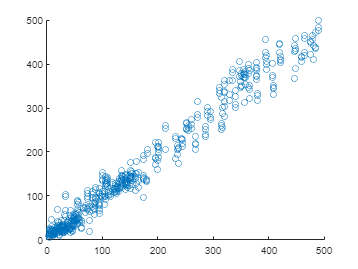


%display target vs pred
figure()
scatter(target.test,pred)

xaiOccMeanId = mean(abs(xaiOcc(:,:,:,:)),4)>0.10;

dataRed = data;
for i = 1:size(dataRed.train,4)
    temp = squeeze(dataRed.train(:,:,1,i));
    temp(xaiOccMeanId) = meanResponse(xaiOccMeanId);
    dataRed.train(:,:,1,i) = temp;
end

for i = 1:size(dataRed.val,4)
    temp = squeeze(dataRed.val(:,:,1,i));
    temp(xaiOccMeanId) = meanResponse(xaiOccMeanId);
    dataRed.val(:,:,1,i) = temp;
end

for i = 1:size(dataRed.test,4)
    temp = squeeze(dataRed.test(:,:,1,i));
    temp(xaiOccMeanId) = meanResponse(xaiOccMeanId);
    dataRed.test(:,:,1,i) = temp;
end

%Generate Model without optim hyperparameter
paraStore = [locationData 'acetoneParams.mat'];
load(paraStore);
tcocnnTest2 = TCOCNN(loadStruct.dataSize,loadStruct.Outputsize,loadStruct.Regression,optim);


%With already optimized variables start training directly
tcocnnTest2.train(dataRed.train,target.train);
%Predict Test Data
pred = tcocnnTest2.apply(dataRed.test);
disp(helpers.RMSE.loss(pred,target.test));

   18.4676



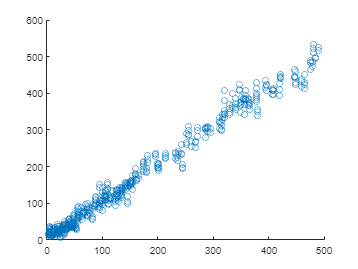


%display target vs pred
figure()
scatter(target.test,pred)